# Analysis

Analysis of data from the 'counterfactual stimuli' experiment.

## Load data

%load collected participant data from study
data_struct = loadData; %comment out if only want to load simulated data

%load simulated data: 1st arg = ModelType ('Null', 'Shifter', 'Scalar')
%2nd arg = numberOfDataPoints (e.g. 35)
%data_struct = loadSimulatedData('Scalar', 35); %uncomment to simulate data

%extract list of subject codes (or simulated data codes)
subj_list = data_struct.keys;

## Initialize

%get colors for plots
addpath('~/Documents/software/cbrewer')
[cb] = cbrewer('qual','Set1',10,'pchip');

## Accuracy

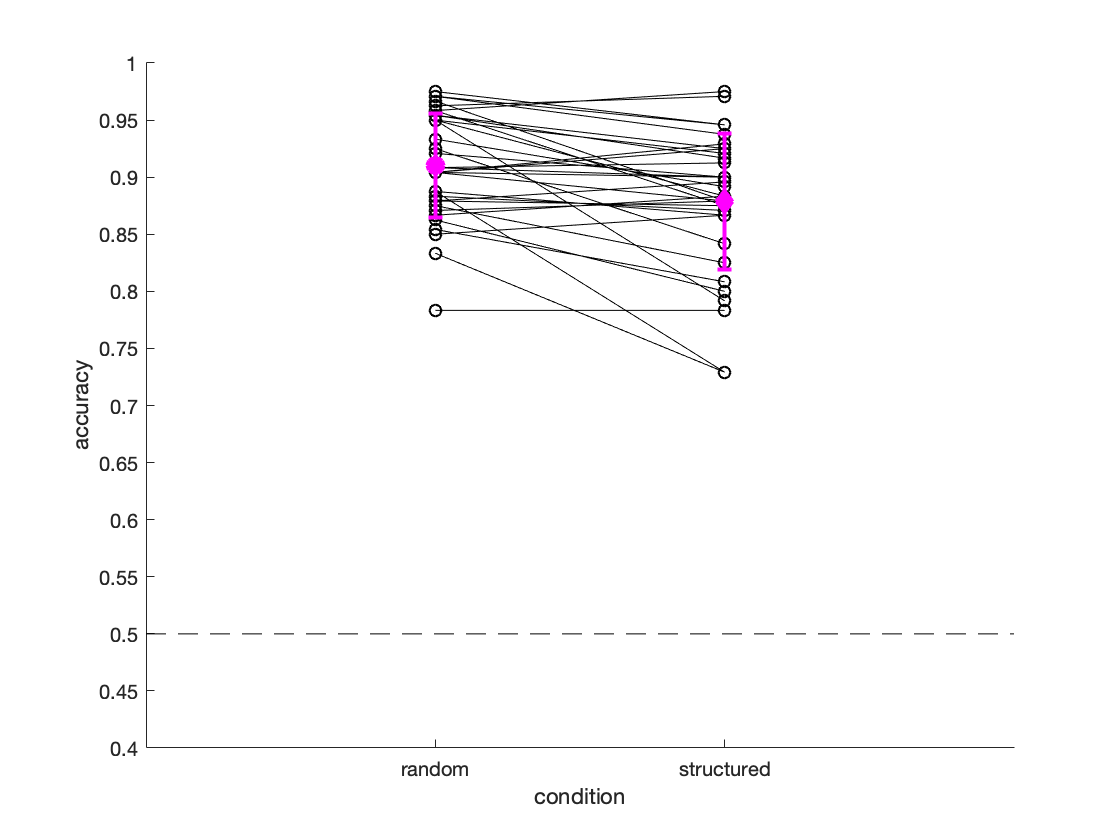

[rand_acc,struct_acc] = deal(nan(numel(subj_list),1)); %initialise with NaN values
[rand_acc_1,rand_acc_2,struct_acc_1,struct_acc_2] = deal(nan(numel(subj_list),1));  %initialise with NaN values

%extract the mean of accuracy for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %per condition
    rand_acc(i_s) = nanmean(data_struct(subj).RandomCorrect);
    struct_acc(i_s) = nanmean(data_struct(subj).StructCorrect);
    
    %per block
    rand_acc_1(i_s) = nanmean(data_struct(subj).RandomCorrect(1:120));
    rand_acc_2(i_s) = nanmean(data_struct(subj).RandomCorrect(121:240));
    struct_acc_1(i_s) = nanmean(data_struct(subj).StructCorrect(1:120));
    struct_acc_2(i_s) = nanmean(data_struct(subj).StructCorrect(121:240));
end

%useful values
rand_acc_mean = nanmean(rand_acc); %random condition mean
rand_acc_std = nanstd(rand_acc); %random condition std
rand_acc_mean_1 = nanmean(rand_acc_1); %random block 1 mean
rand_acc_std_1 = nanstd(rand_acc_1); %random block 1 std
rand_acc_mean_2 = nanmean(rand_acc_2); %random block 2 mean
rand_acc_std_2 = nanstd(rand_acc_2); %random block 2 std
struct_acc_mean = nanmean(struct_acc); %structured condition mean
struct_acc_std = nanstd(struct_acc); %structured condition std
struct_acc_mean_1 = nanmean(struct_acc_1); %structured block 1 mean
struct_acc_std_1 = nanstd(struct_acc_1); %structured block 1 std
struct_acc_mean_2 = nanmean(struct_acc_2); %structured block 2 mean
struct_acc_std_2 = nanstd(struct_acc_2); %structured block 2 std

%plot mean accuracy for each participant for both conditions
figure; hold on;
plot([rand_acc';struct_acc'], '-ok')
errorbar(1,rand_acc_mean,rand_acc_std,'om','MarkerFaceColor',...
    'm','MarkerSize',8,'LineWidth',2)
errorbar(2,struct_acc_mean,struct_acc_std,'dm','MarkerFaceColor',...
    'm','MarkerSize',8,'LineWidth',2)
ylim([0.4,1]); ylabel('accuracy');
set(gca,'ytick',[0.4:0.05:1])
xlim([0,3]); xlabel('condition');
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
plot([0,3],[0.5,0.5],'k--')
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanAccuracy','-dpng','-r600');

sprintf('Random Accuracy (mean ± std) = %.2f ± %.2f; Structured Accuracy (mean, std) = %.2f ± %.2f',...
    rand_acc_mean, rand_acc_std, struct_acc_mean, struct_acc_std)

ans = 'Random Accuracy (mean ± std) = 0.91 ± 0.05; Structured Accuracy (mean, std) = 0.88 ± 0.06'

%check significance
[h,p,ci,stats] = ttest(rand_acc,struct_acc);
sprintf(['Significance test: Difference in accuracy between structured and random conditions:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in accuracy between structured and random conditions: t(34)=4.00, p=0.00032'

## Confidence

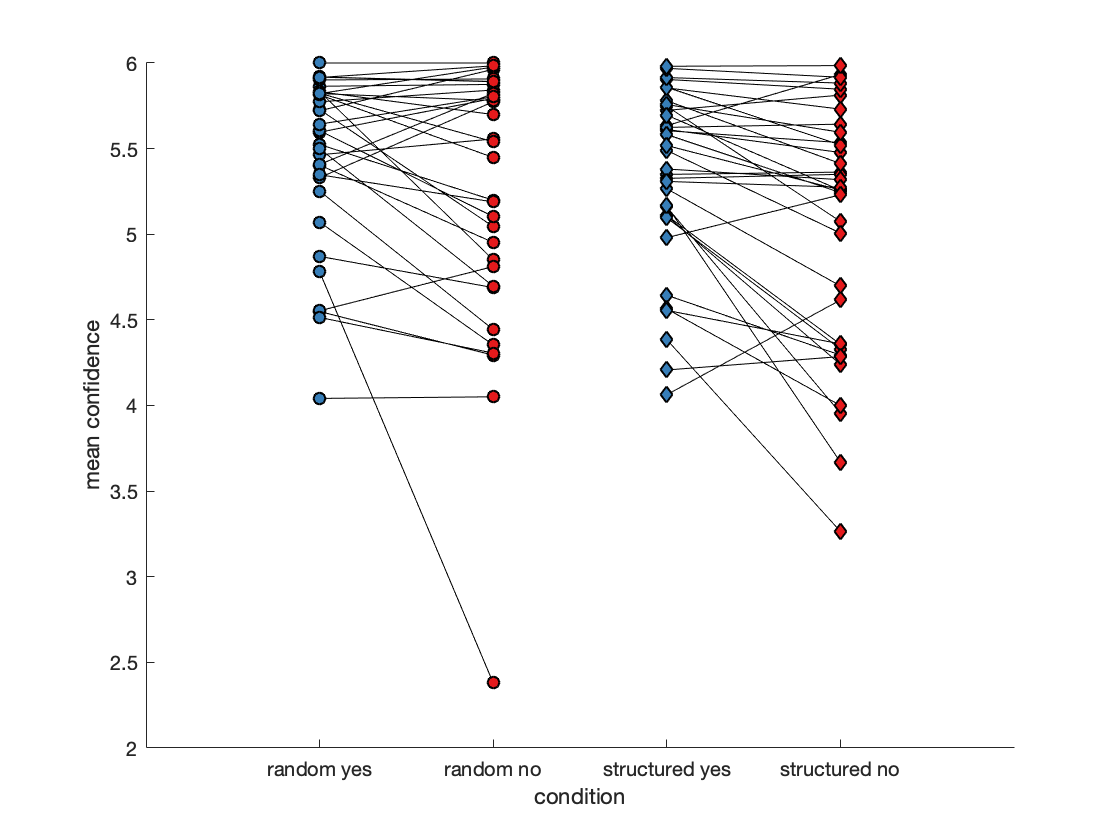

[rand_yes_conf,rand_no_conf,struct_yes_conf, struct_no_conf] = deal(nan(1,numel(subj_list))); %initialise with NaN values

%extract the mean of confidence for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==1));
    rand_no_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==0));
    struct_yes_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==1));
    struct_no_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==0));
end

%plot mean confidence for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_conf;rand_no_conf],'k');
plot(3:4,[struct_yes_conf;struct_no_conf],'k');
scatter(ones(length(subj_list),1),rand_yes_conf,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_conf,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_conf,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_conf,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanConfidence','-dpng','-r600');

%useful values
[rand_yes_conf_mean,rand_no_conf_mean,struct_yes_conf_mean, struct_no_conf_mean] = ...
    deal(nanmean(rand_yes_conf),nanmean(rand_no_conf),nanmean(struct_yes_conf),nanmean(struct_no_conf));
[rand_yes_conf_std,rand_no_conf_std,struct_yes_conf_std, struct_no_conf_std] = ...
    deal(nanstd(rand_yes_conf),nanstd(rand_no_conf),nanstd(struct_yes_conf),nanstd(struct_no_conf));

sprintf('Random Yes Confidence (mean ± std) = %.2f ± %.2f; Random No Confidence (mean, std) = %.2f ± %.2f',...
    rand_yes_conf_mean, rand_yes_conf_std, rand_no_conf_mean, rand_no_conf_std)

ans = 'Random Yes Confidence (mean ± std) = 5.49 ± 0.50; Random No Confidence (mean, std) = 5.28 ± 0.79'

sprintf('Structured Yes Confidence (mean ± std) = %.2f ± %.2f; Structured No Confidence (mean, std) = %.2f ± %.2f',...
    struct_yes_conf_mean, struct_yes_conf_std, struct_no_conf_mean, struct_no_conf_std)

ans = 'Structured Yes Confidence (mean ± std) = 5.34 ± 0.52; Structured No Confidence (mean, std) = 5.05 ± 0.72'

%check significance
[h,p,ci,stats] = ttest(rand_no_conf,struct_no_conf);
sprintf(['Significance test: Difference in confidence between structured and random conditions in "no" responses:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in confidence between structured and random conditions in "no" responses: t(34)=2.70, p=0.01061'

[h,p,ci,stats] = ttest(rand_yes_conf,struct_yes_conf);
sprintf(['Significance test: Difference in confidence between structured and random conditions in "yes" responses:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in confidence between structured and random conditions in "yes" responses: t(34)=3.01, p=0.00493'

[h,p,ci,stats] = ttest(rand_no_conf,rand_yes_conf);
sprintf(['Significance test: Difference in confidence between "yes" and "no" responses in the random condition:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in confidence between "yes" and "no" responses in the random condition: t(34)=-2.37, p=0.02337'

[h,p,ci,stats] = ttest(struct_no_conf,struct_yes_conf);
sprintf(['Significance test: Difference in confidence between "yes" and "no" responses in the structured condition:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in confidence between "yes" and "no" responses in the structured condition: t(34)=-3.92, p=0.00041'

## Visibility-confidence correlation

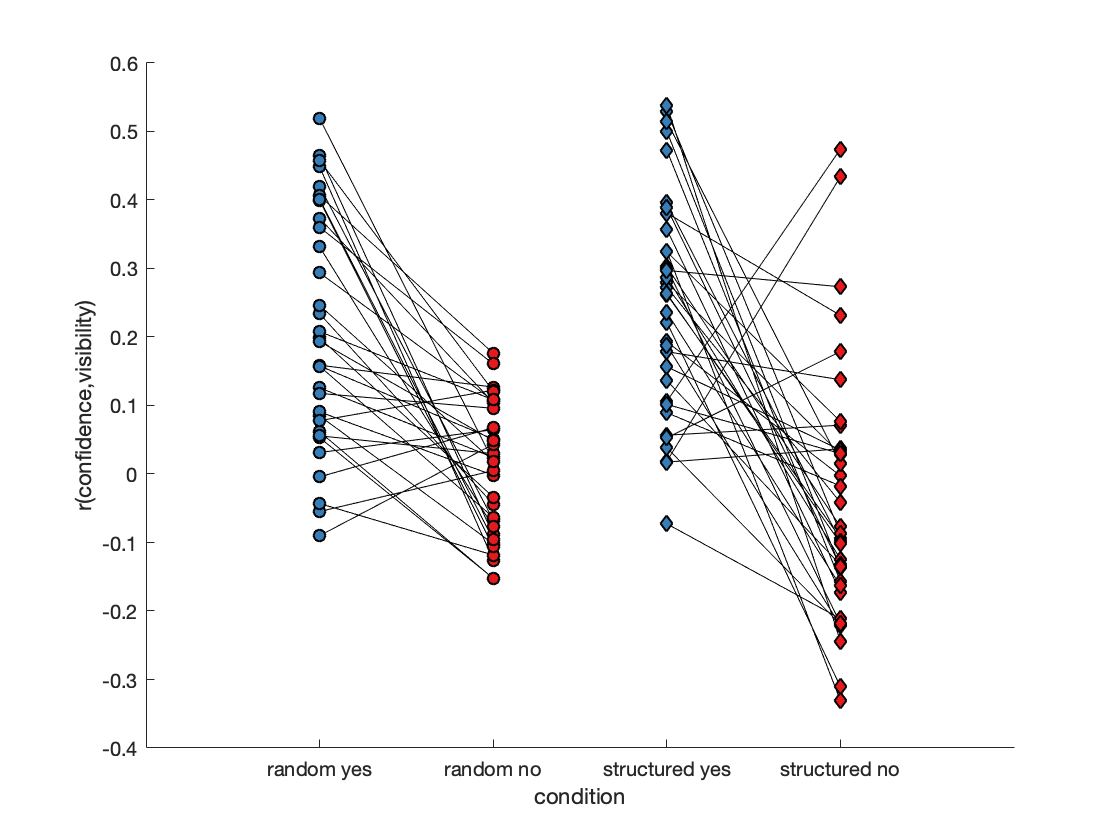

[rand_yes_VCcorr,struct_yes_VCcorr, rand_no_VCcorr, struct_no_VCcorr] = deal(nan(size(subj_list)));%initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned confidence and visibility vectors in both conditions
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
    demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
    
    %calculate the visibility-confidence correlation (Spearman's rank) for each participant
    
    %random condition
    rand_yes_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %structured condition
    rand_no_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
    struct_no_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
end

%plot the visibility-confidence correlation for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_VCcorr;rand_no_VCcorr],'k');
plot(3:4,[struct_yes_VCcorr;struct_no_VCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisConf','-dpng','-r600');

%significance test
[h,p,ci,stats] = ttest(struct_no_VCcorr,rand_no_VCcorr);
sprintf(['Significance test: Difference in visibility-confidence correlations between ' ...
    'structured and random conditions in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-confidence correlations between structured and random conditions in "no" responses: t(32)=-1.24, p=0.22445'

[h,p,ci,stats] = ttest(struct_yes_VCcorr,rand_yes_VCcorr);
sprintf(['Significance test: Difference in visibility-confidence correlations between ' ...
    'structured and random conditions in "yes" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-confidence correlations between structured and random conditions in "yes" responses: t(32)=1.70, p=0.09837'

[h,p,ci,stats] = ttest(struct_no_VCcorr);
sprintf(['Significance test: Visibility-confidence correlations in the ' ...
    'structured condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-confidence correlations in the structured condition in "no" responses: t(34)=-1.14, p=0.26304'

[h,p,ci,stats] = ttest(rand_no_VCcorr);
sprintf(['Significance test: Visibility-confidence correlations in the ' ...
    'random condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-confidence correlations in the random condition in "no" responses: t(32)=0.48, p=0.63201'

[h,p,ci,stats] = ttest(struct_yes_VCcorr);
sprintf(['Significance test: Visibility-confidence correlations in the ' ...
    'structured condition in "yes" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-confidence correlations in the structured condition in "yes" responses: t(34)=9.20, p=0.00000'

[h,p,ci,stats] = ttest(rand_yes_VCcorr);
sprintf(['Significance test: Visibility-confidence correlations in the ' ...
    'random condition in "yes" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-confidence correlations in the random condition in "yes" responses: t(32)=7.01, p=0.00000'

[h,p,ci,stats] = ttest(struct_no_VCcorr,struct_yes_VCcorr);
sprintf(['Significance test: Difference in visibility-confidence correlations between ' ...
    '"yes" and "no" responses in the structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-confidence correlations between "yes" and "no" responses in the structured condition: t(34)=-6.01, p=0.00000'

[h,p,ci,stats] = ttest(rand_no_VCcorr,rand_yes_VCcorr);
sprintf(['Significance test: Difference in visibility-confidence correlations between ' ...
    '"yes" and "no" responses in the random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-confidence correlations between "yes" and "no" responses in the random condition: t(32)=-5.97, p=0.00000'

## Response bias

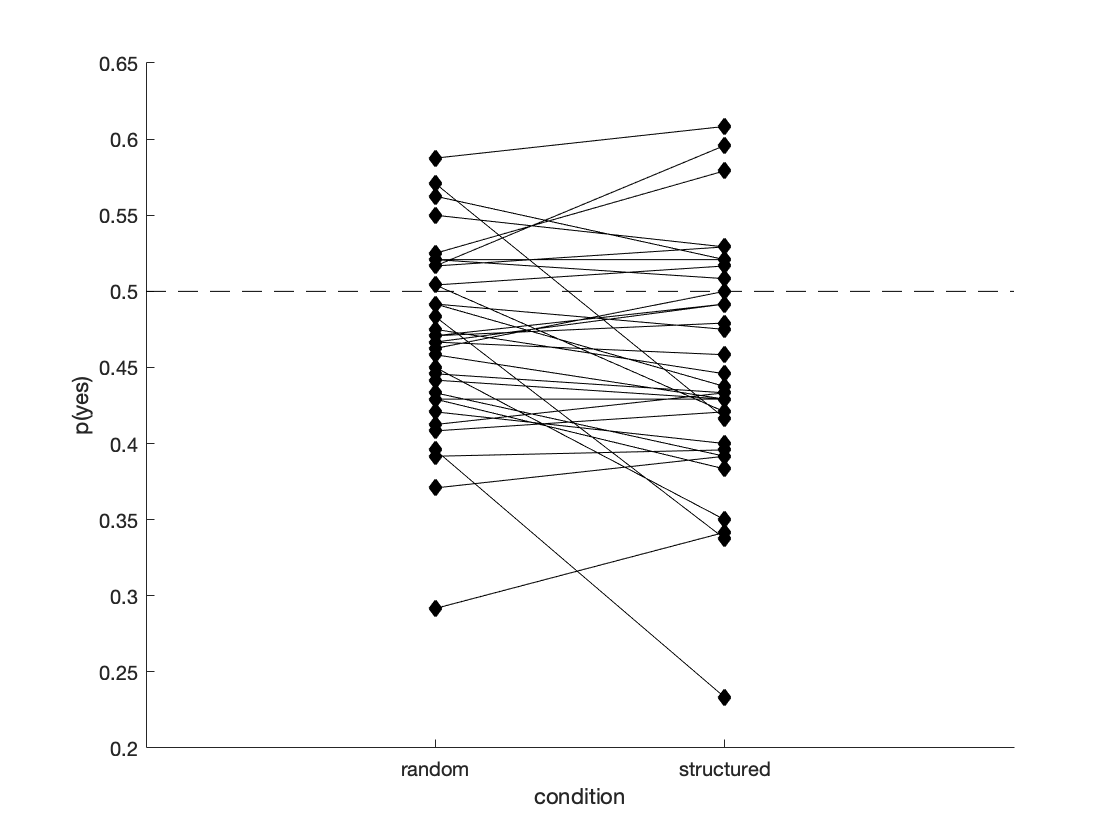

[rand_Pyes,struct_Pyes] = deal(nan(numel(subj_list),1)); %initialise with NaN values

%extract the probability of saying "yes" (p(yes)) for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_Pyes(i_s) = nanmean(data_struct(subj).RandomResp==1);
    struct_Pyes(i_s) = nanmean(data_struct(subj).StructResp==1);
end

%plot p(yes) for each participant for both conditions
figure; hold on;
plot([rand_Pyes';struct_Pyes'],'-dk','MarkerFaceColor','k');
ylabel('p(yes)');
xlim([0,3]); xlabel('condition');
plot([0,3],[0.5,0.5],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/responseBias','-dpng','-r600');

%useful values
[rand_Pyes_mean,struct_Pyes_mean] = ...
    deal(nanmean(rand_Pyes),nanmean(struct_Pyes));
[rand_Pyes_std,struct_Pyes_std] = ...
    deal(nanstd(rand_Pyes),nanstd(struct_Pyes));
sprintf('Random p(Yes) (mean ± std) = %.2f ± %.2f; Structured p(Yes) (mean, std) = %.2f ± %.2f',...
    rand_Pyes_mean, rand_Pyes_std, struct_Pyes_mean, struct_Pyes_std)

ans = 'Random p(Yes) (mean ± std) = 0.47 ± 0.06; Structured p(Yes) (mean, std) = 0.45 ± 0.08'

%check significance
[h,p,ci,stats] = ttest(rand_Pyes,0.5);
sprintf(['Significance test: p(yes) (response bias) in the ' ...
    'random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: p(yes) (response bias) in the random condition: t(34)=-3.15, p=0.00341'

[h,p,ci,stats] = ttest(struct_Pyes,0.5);
sprintf(['Significance test: p(yes) (response bias) in the ' ...
    'structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: p(yes) (response bias) in the structured condition: t(34)=-3.81, p=0.00056'

[h,p,ci,stats] = ttest(rand_Pyes,struct_Pyes);
sprintf(['Significance test: Difference in p(yes) (response bias) between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in p(yes) (response bias) between the structured and random conditions: t(34)=1.86, p=0.07187'

## Visibility-response correlation

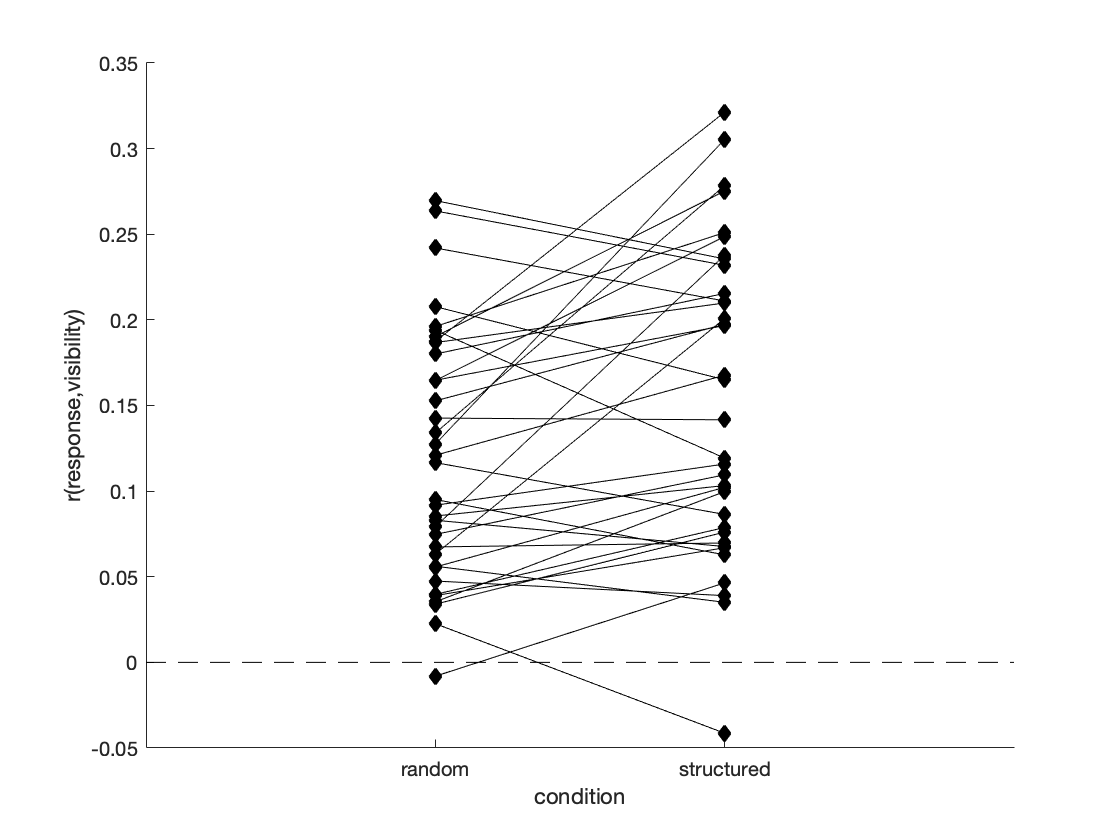

[rand_resp_corr,struct_resp_corr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %calculate the visibility-confidence correlation (Spearman's rank) for each participant
    
    %random condition
    rand_resp_corr(i_s) = nancorr(data_struct(subj).RandomDemeanVisibility, data_struct(subj).RandomResp);
    %structured condition
    struct_resp_corr(i_s) = nancorr(data_struct(subj).StructDemeanVisibility, data_struct(subj).StructResp);
end

%plot the visibility-response correlation for each participant for both conditions
figure; hold on;
plot([rand_resp_corr;struct_resp_corr],'-dk','MarkerFaceColor','k');
ylabel('r(response,visibility)');
xlim([0,3]); xlabel('condition');
plot([0,3],[0,0],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisResp','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(struct_resp_corr-rand_resp_corr);
sprintf(['Significance test: Difference in visibility-response correlations between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-response correlations between the structured and random conditions: t(34)=3.01, p=0.005'

## Response Time

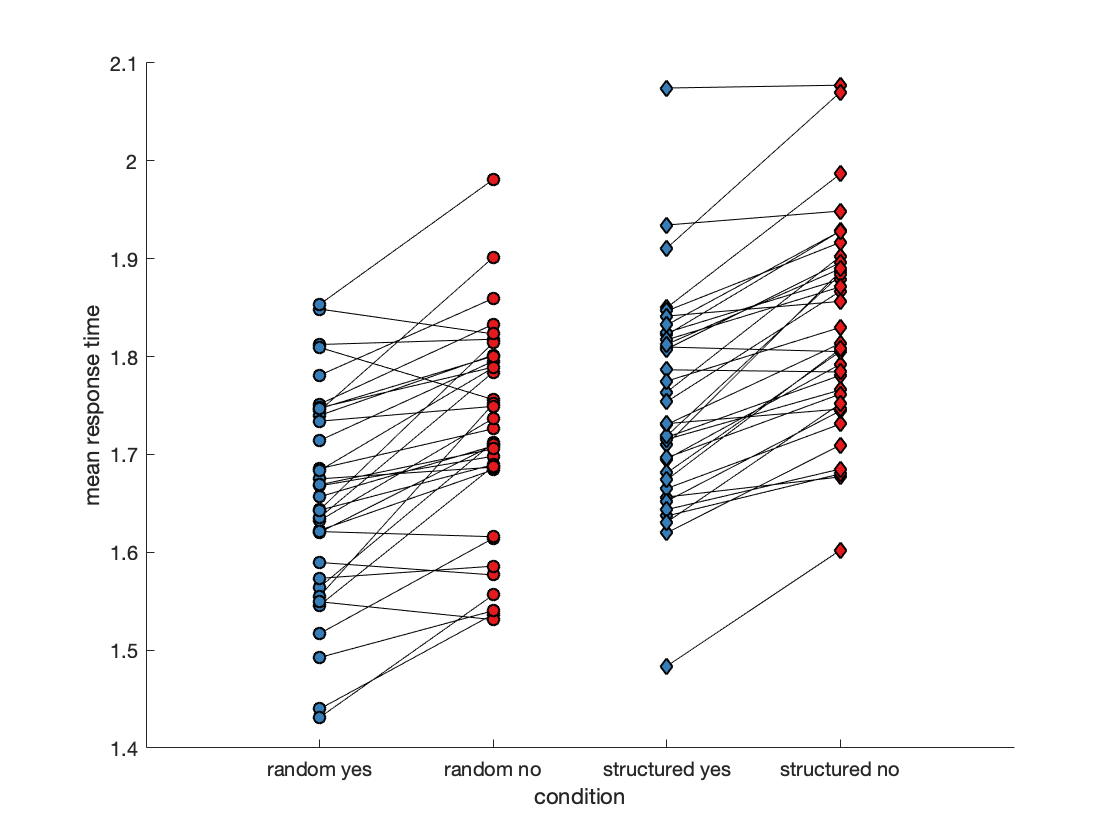

[rand_yes_RT,rand_no_RT,struct_yes_RT, struct_no_RT] = deal(nan(1,numel(subj_list))); %initialise with NaN values

%extract the mean of response time (RT) for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==1));
    rand_no_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==0));
    struct_yes_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==1));
    struct_no_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==0));
end

%plot the mean RT for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_RT;rand_no_RT],'k');
plot(3:4,[struct_yes_RT;struct_no_RT],'k');
scatter(ones(length(subj_list),1),rand_yes_RT,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_RT,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_RT,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_RT,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('mean response time');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanRT','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(rand_no_RT,struct_no_RT);
sprintf(['Significance test: Difference in RT between structured and random conditions in "no" responses:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in RT between structured and random conditions in "no" responses: t(34)=-10.37, p=0.00000'

[h,p,ci,stats] = ttest(rand_yes_RT,struct_yes_RT);
sprintf(['Significance test: Difference in RT between structured and random conditions in "yes" responses:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in RT between structured and random conditions in "yes" responses: t(34)=-9.49, p=0.00000'

[h,p,ci,stats] = ttest(rand_no_RT,rand_yes_RT);
sprintf(['Significance test: Difference in RT between "yes" and "no" responses in the random condition:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in RT between "yes" and "no" responses in the random condition: t(34)=6.52, p=0.00000'

[h,p,ci,stats] = ttest(struct_no_RT,struct_yes_RT);
sprintf(['Significance test: Difference in RT between "yes" and "no" responses in the structured condition:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in RT between "yes" and "no" responses in the structured condition: t(34)=9.39, p=0.00000'

## Visibility-RT correlation

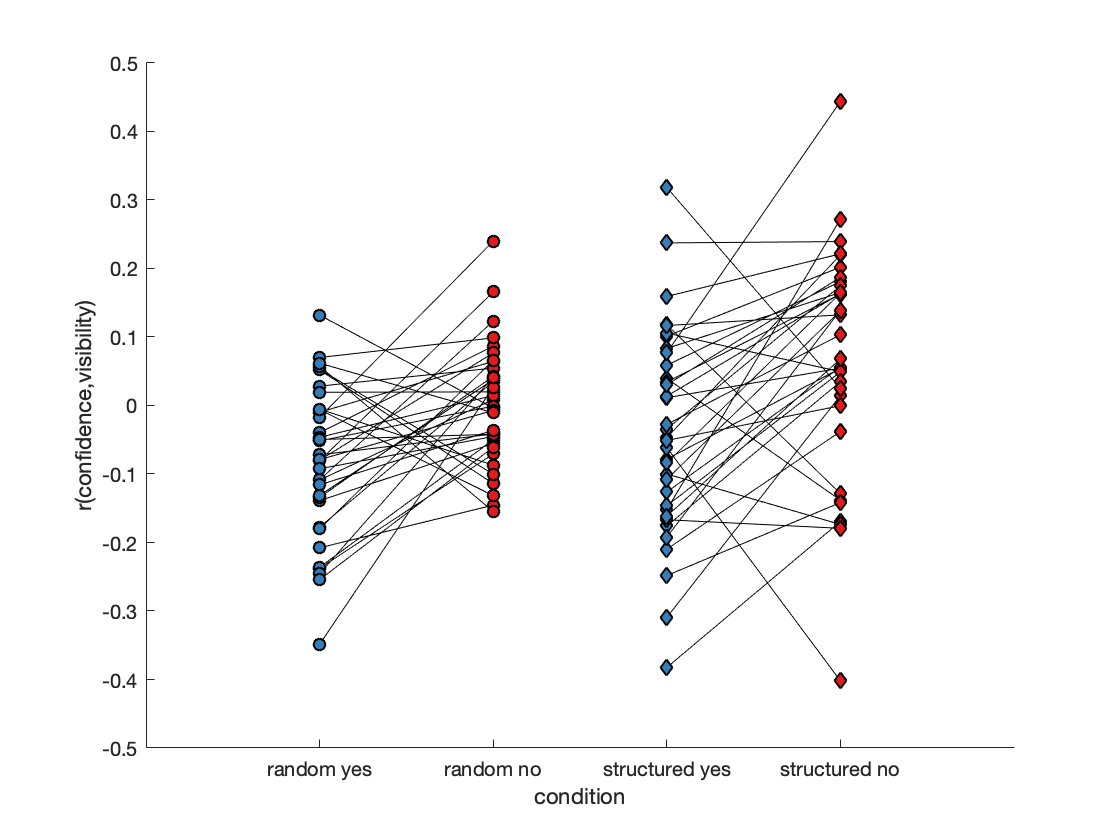

[rand_yes_VRTcorr,struct_yes_VRTcorr, rand_no_VRTcorr, struct_no_VRTcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned RT and visibility vectors in both conditions
    demeaned_random_RT = data_struct(subj).RandomDemeanRT;
    demeaned_struct_RT = data_struct(subj).StructDemeanRT;
    demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
    demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
    
    %calculate the visibility-RT correlation (Spearman's rank) for each participant
    
    %random condition
    rand_yes_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %structured condition
    rand_no_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1));
    struct_no_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0  & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
end

%plot the visibility-RT correlation for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_VRTcorr;rand_no_VRTcorr],'k');
plot(3:4,[struct_yes_VRTcorr;struct_no_VRTcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_VRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_VRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_VRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_VRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisRT','-dpng','-r600');

%significance test
[h,p,ci,stats] = ttest(struct_no_VRTcorr,rand_no_VRTcorr);
sprintf(['Significance test: Difference in visibility-RT correlations between ' ...
    'structured and random conditions in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in visibility-RT correlations between structured and random conditions in "no" responses: t(34)=1.91, p=0.06456'

[h,p,ci,stats] = ttest(struct_no_VRTcorr);
sprintf(['Significance test: Visibility-RT correlations in the ' ...
    'structured condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-RT correlations in the structured condition in "no" responses: t(34)=2.42, p=0.02108'

[h,p,ci,stats] = ttest(rand_no_VRTcorr);
sprintf(['Significance test: Visibility-RT correlations in the ' ...
    'random condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Visibility-RT correlations in the random condition in "no" responses: t(34)=0.09, p=0.93121'

## E(Visibility)-confidence correlation

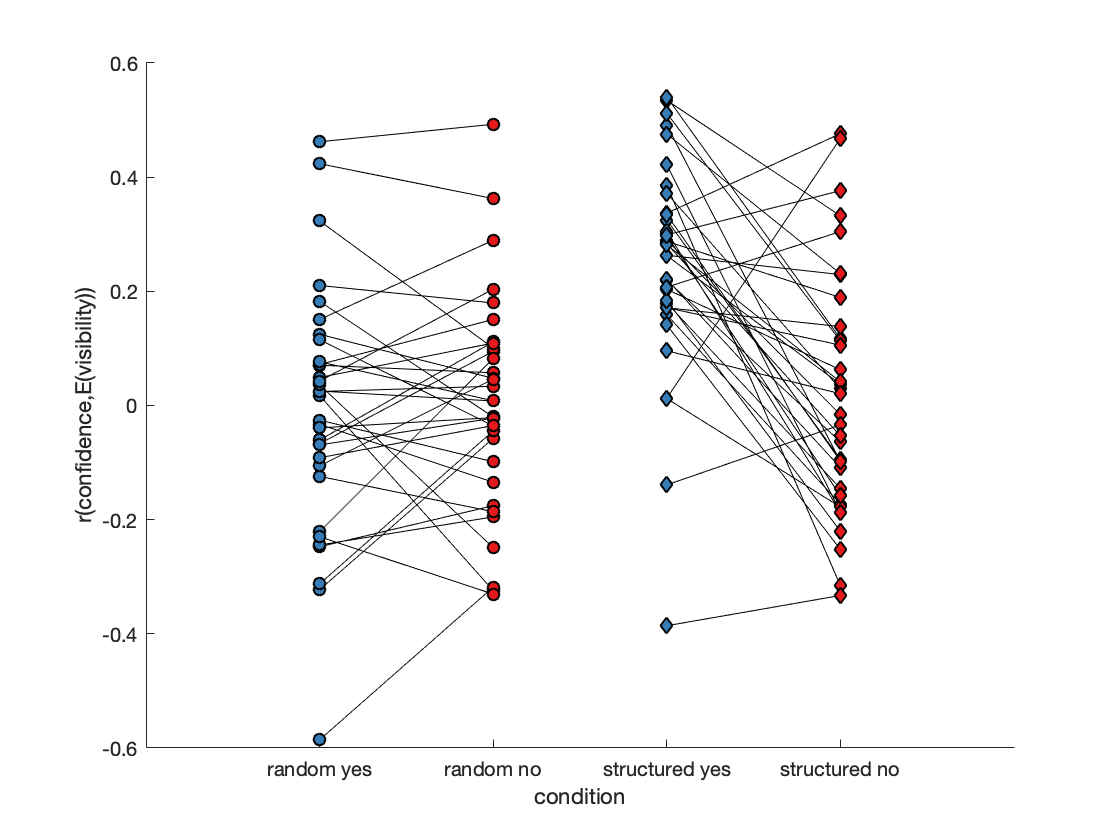

[rand_yes_EVCcorr,struct_yes_EVCcorr, rand_no_EVCcorr, struct_no_EVCcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned expected visibility vectors for both conditions
    
    demeaned_random_Evis = data_struct(subj).RandomDemeanEV;
    demeaned_struct_Evis = data_struct(subj).StructDemeanEV;
    
    %extract demeaned confidence vectors for both conditions
    
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    
    %calculate correlation between expected visibility and confidence
    
    %structured condition
    struct_yes_EVCcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    struct_no_EVCcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
    %random condition
    rand_yes_EVCcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    rand_no_EVCcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
end

%plot correlation between expected visibility and confidence
figure; hold on;
plot(1:2,[rand_yes_EVCcorr;rand_no_EVCcorr],'k');
plot(3:4,[struct_yes_EVCcorr;struct_no_EVCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(confidence,E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisConf','-dpng','-r600');

%significance test
[h,p,ci,stats] = ttest(struct_no_EVCcorr,rand_no_EVCcorr);
sprintf(['Significance test: Difference in E(visibility)-confidence correlations between ' ...
    'structured and random conditions in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-confidence correlations between structured and random conditions in "no" responses: t(32)=0.03, p=0.97517'

[h,p,ci,stats] = ttest(rand_yes_EVCcorr,struct_yes_EVCcorr);
sprintf(['Significance test: Difference in  E(visibility)-confidence between' ...
    ' structured and random conditions in "yes" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in  E(visibility)-confidence between structured and random conditions in "yes" responses: t(32)=-4.69, p=0.00005'

[h,p,ci,stats] = ttest(struct_no_EVCcorr);
sprintf(['Significance test: E(visibility)-confidence correlations in the ' ...
    'structured condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-confidence correlations in the structured condition in "no" responses: t(34)=0.44, p=0.66010'

[h,p,ci,stats] = ttest(rand_no_EVCcorr);
sprintf(['Significance test: E(visibility)-confidence correlations in the ' ...
    'random condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-confidence correlations in the random condition in "no" responses: t(32)=0.12, p=0.90412'

[h,p,ci,stats] = ttest(rand_no_EVCcorr,rand_yes_EVCcorr);
sprintf(['Significance test: Difference in E(visibility)-confidence correlations... ' ...
    'between "yes" and "no" responses in the random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-confidence correlations... between "yes" and "no" responses in the random condition: t(32)=0.55, p=0.58327'

[h,p,ci,stats] = ttest(struct_no_EVCcorr,struct_yes_EVCcorr);
sprintf(['Significance test: Difference in E(visibility)-confidence correlations... ' ...
    'between "yes" and "no" responses in the structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-confidence correlations... between "yes" and "no" responses in the structured condition: t(34)=-5.67, p=0.00000'

## E(Visibility)-response correlation

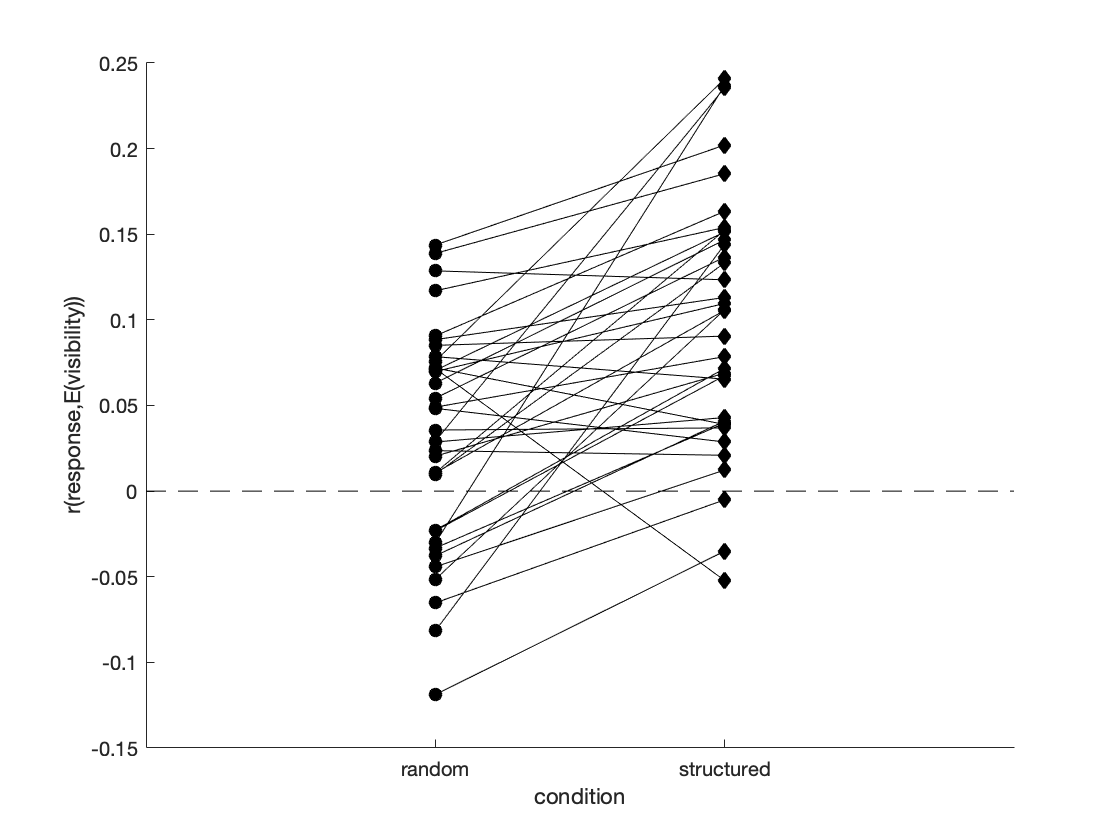

[rand_resp_EVcorr,struct_resp_EVcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned expected visibility vectors for both conditions
    
    demeaned_random_Evis = data_struct(subj).RandomDemeanEV;
    demeaned_struct_Evis = data_struct(subj).StructDemeanEV;

    %calculate correlation between expected visibility and response
    
    %structured condition
    struct_resp_EVcorr(i_s) = nancorr(demeaned_struct_Evis, data_struct(subj).StructResp);
    %random condition
    rand_resp_EVcorr(i_s) = nancorr(demeaned_random_Evis, data_struct(subj).RandomResp);
    
end
    
%plot correlation between expected visibility and response
figure; hold on;
plot([rand_resp_EVcorr;struct_resp_EVcorr],'-k');
scatter(ones(length(subj_list),1),rand_resp_EVcorr,[],'o','MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
scatter(2*ones(length(subj_list),1),struct_resp_EVcorr,[],'d','MarkerEdgeColor','k','MarkerFaceColor','k','LineWidth',1);
ylabel('r(response,E(visibility))');
xlim([0,3]); xlabel('condition');
plot([0,3],[0,0],'k--')
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisResp','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(struct_resp_EVcorr,rand_resp_EVcorr);
sprintf(['Significance test: Difference in E(visibility)-response correlations between ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-response correlations between structured and random conditions: t(34)=5.15, p=0.00001'

[h,p,ci,stats] = ttest(struct_resp_EVcorr);
sprintf(['Significance test: E(visibility)-response correlations in the ' ...
    'structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-response correlations in the structured condition: t(34)=7.84, p=0.00000'

[h,p,ci,stats] = ttest(rand_resp_EVcorr);
sprintf(['Significance test: E(visibility)-response correlations in the ' ...
    'random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-response correlations in the random condition: t(34)=2.91, p=0.00639'

## E(Visibility)-RT correlation

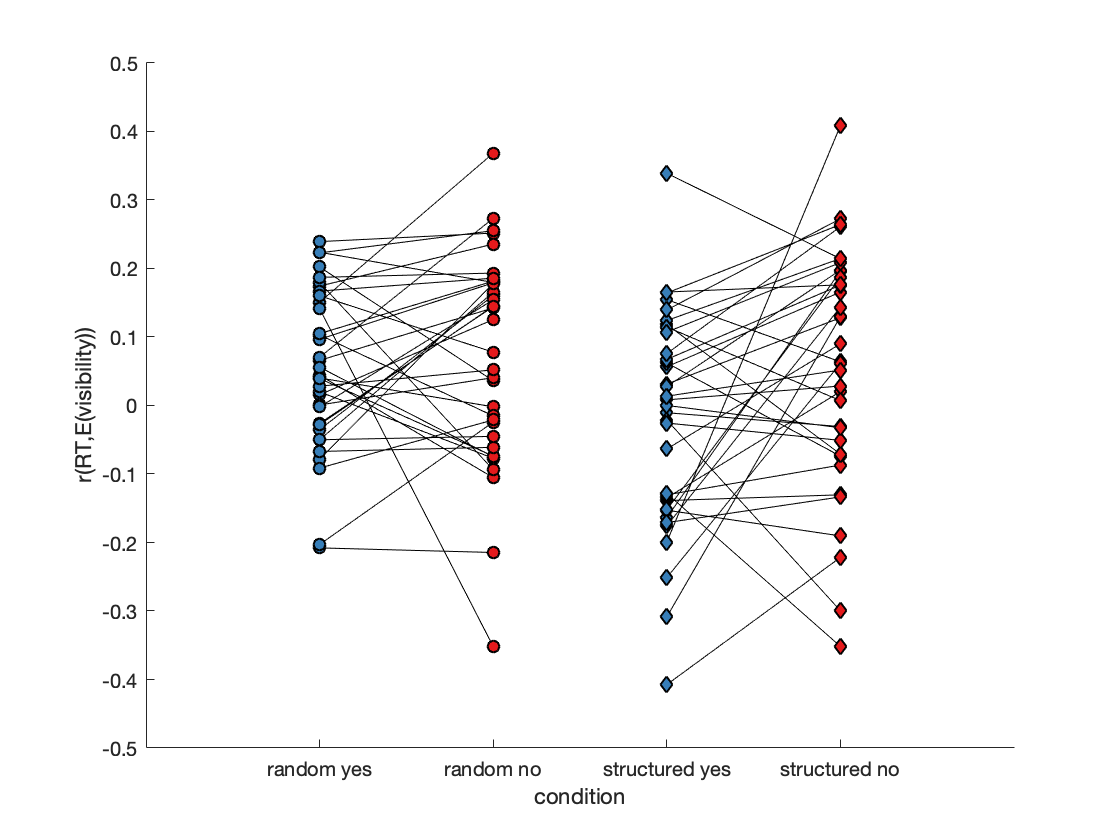

[rand_yes_EVRTcorr,struct_yes_EVRTcorr, rand_no_EVRTcorr, struct_no_EVRTcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned expected visibility vectors for both conditions
    
    demeaned_random_Evis = data_struct(subj).RandomDemeanEV;
    demeaned_struct_Evis = data_struct(subj).StructDemeanEV;

    %calculate correlation between expected visibility and log RT
    
    %structured condition
    struct_yes_EVRTcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        data_struct(subj).StructRT(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    struct_no_EVRTcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        data_struct(subj).StructRT(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
    %random condition
    rand_yes_EVRTcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        data_struct(subj).RandomRT(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    rand_no_EVRTcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        data_struct(subj).RandomRT(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
    
end
    
%plot correlation between expected visibility and RT
figure; hold on;
plot(1:2,[rand_yes_EVRTcorr;rand_no_EVRTcorr],'k');
plot(3:4,[struct_yes_EVRTcorr;struct_no_EVRTcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_EVRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_EVRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_EVRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_EVRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
ylabel('r(RT,E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisRT','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(struct_no_EVRTcorr,rand_no_EVRTcorr);
sprintf(['Significance test: Difference in E(visibility)-RT correlations between ' ...
    'structured and random conditions in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-RT correlations between structured and random conditions in "no" responses: t(34)=-0.42, p=0.67522'

[h,p,ci,stats] = ttest(struct_yes_EVRTcorr,rand_yes_EVRTcorr);
sprintf(['Significance test: Difference in E(visibility)-RT correlations between ' ...
    'structured and random conditions in "yes" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-RT correlations between structured and random conditions in "yes" responses: t(34)=-2.58, p=0.01441'

[h,p,ci,stats] = ttest(struct_no_EVRTcorr);
sprintf(['Significance test: E(visibility)-RT correlations in the ' ...
    'structured condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-RT correlations in the structured condition in "no" responses: t(34)=1.93, p=0.06153'

[h,p,ci,stats] = ttest(rand_no_EVRTcorr);
sprintf(['Significance test: E(visibility)-RT correlations in the ' ...
    'random condition in "no" responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-RT correlations in the random condition in "no" responses: t(34)=2.85, p=0.00736'

[h,p,ci,stats] = ttest(rand_no_EVRTcorr,rand_yes_EVRTcorr);
sprintf(['Significance test: Difference in E(visibility)-RT correlations between "yes" and "no" ' ...
    'responses in the random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-RT correlations between "yes" and "no" responses in the random condition: t(34)=0.73, p=0.46828'

[h,p,ci,stats] = ttest(struct_no_EVRTcorr,struct_yes_EVRTcorr);
sprintf(['Significance test: Difference in E(visibility)-RT correlations between "yes" and "no" ' ...
    'responses in the structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in E(visibility)-RT correlations between "yes" and "no" responses in the structured condition: t(34)=2.55, p=0.01553'

## Response-conditional ROC curves

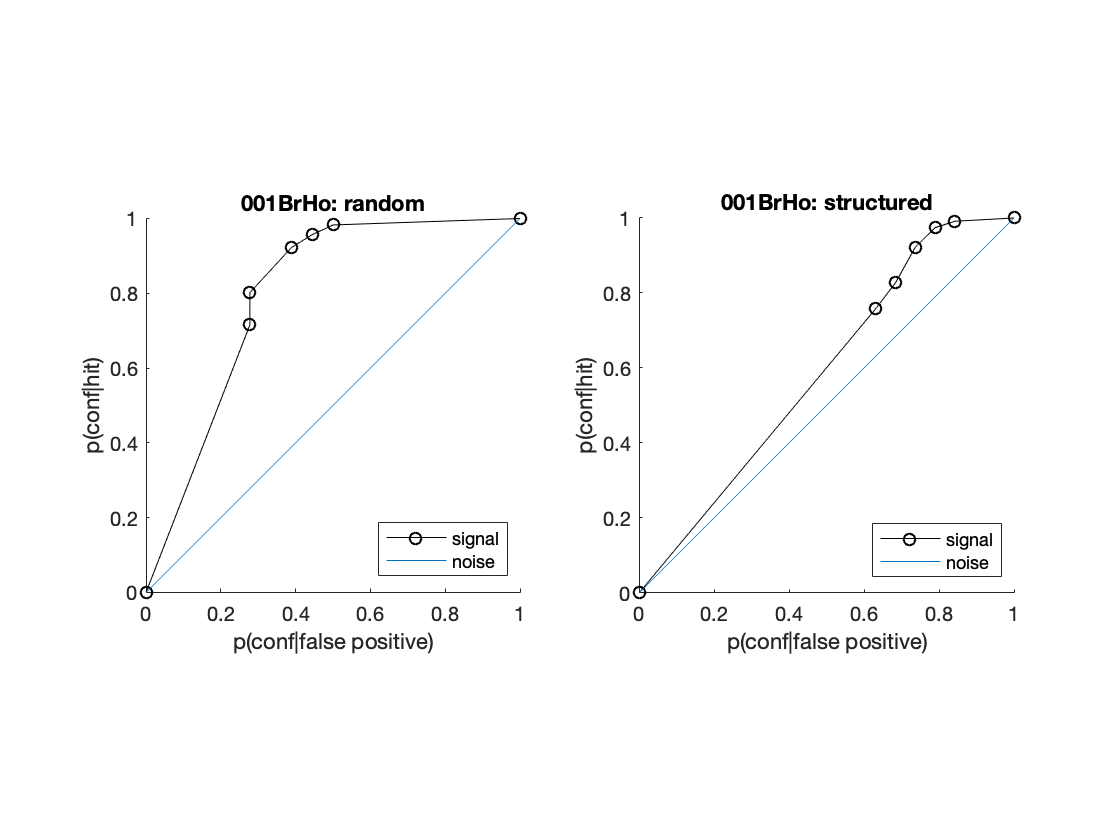

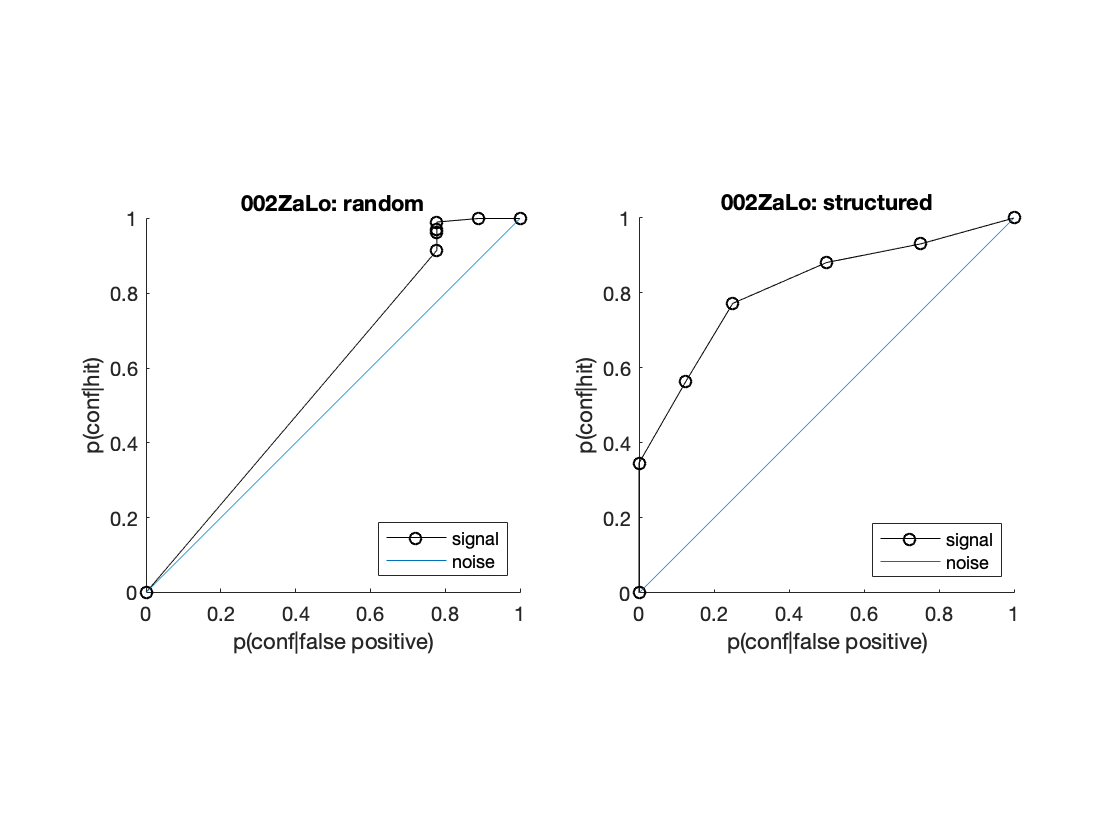

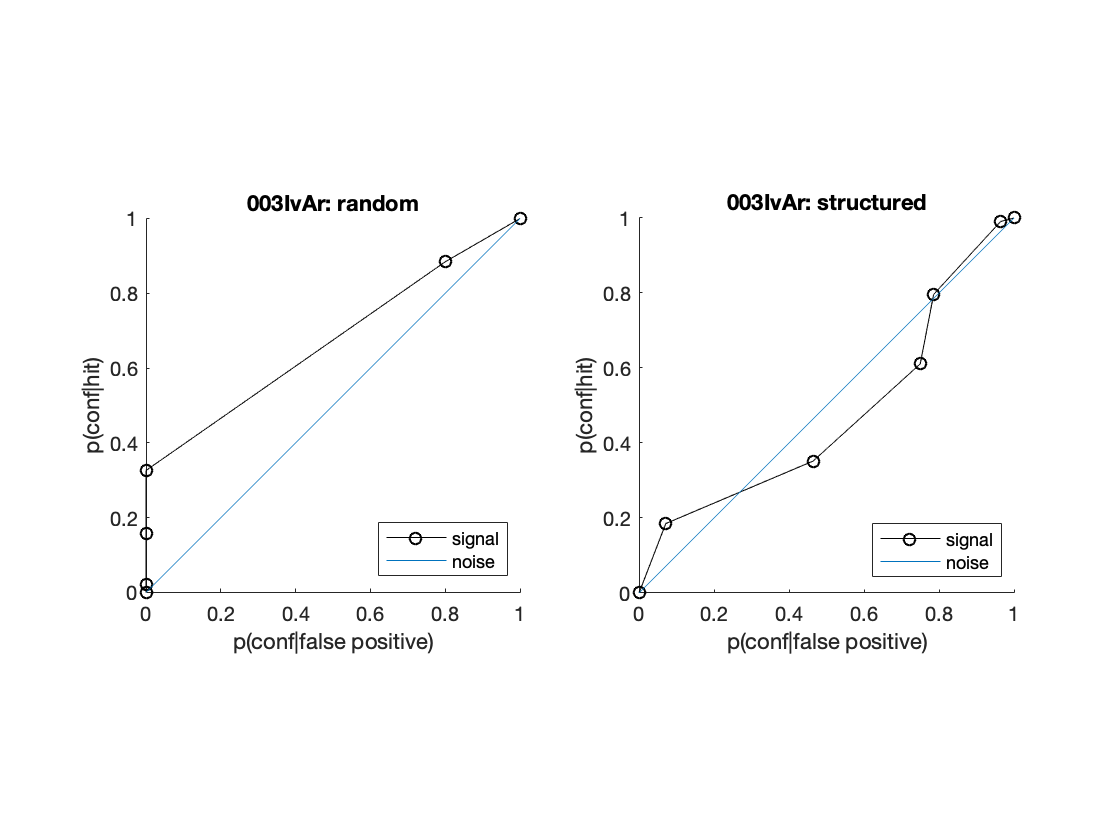

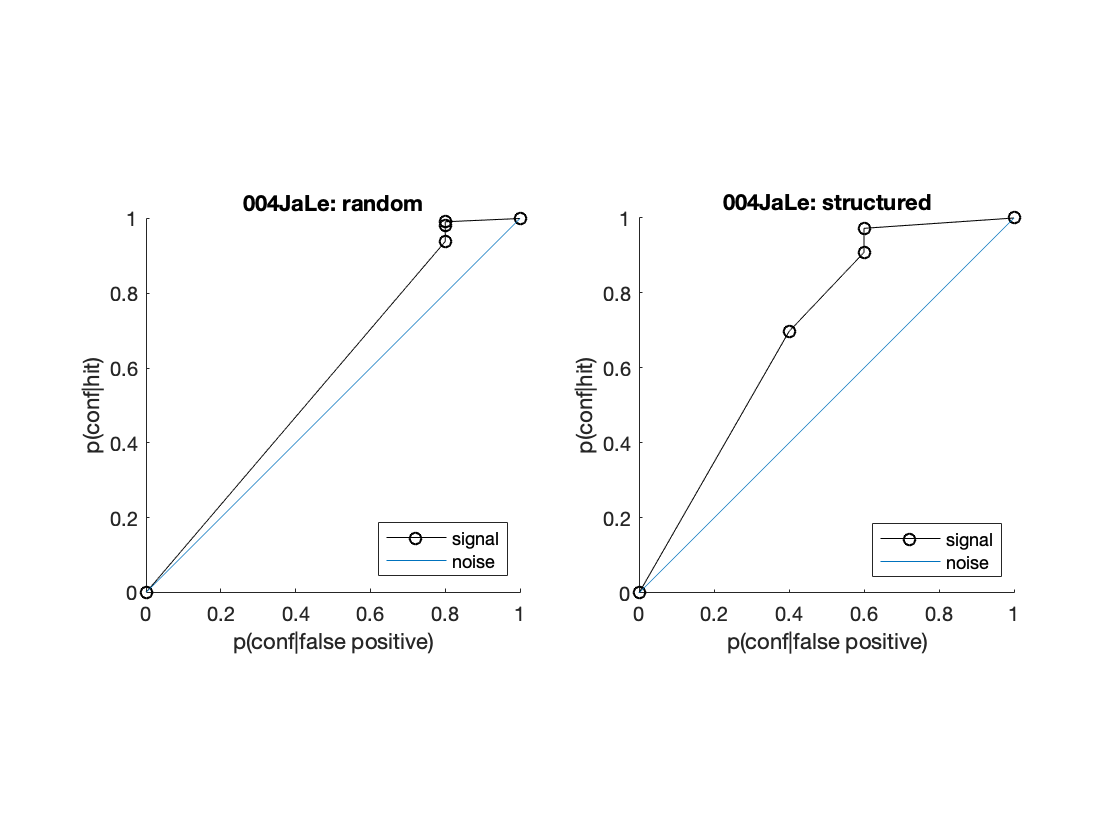

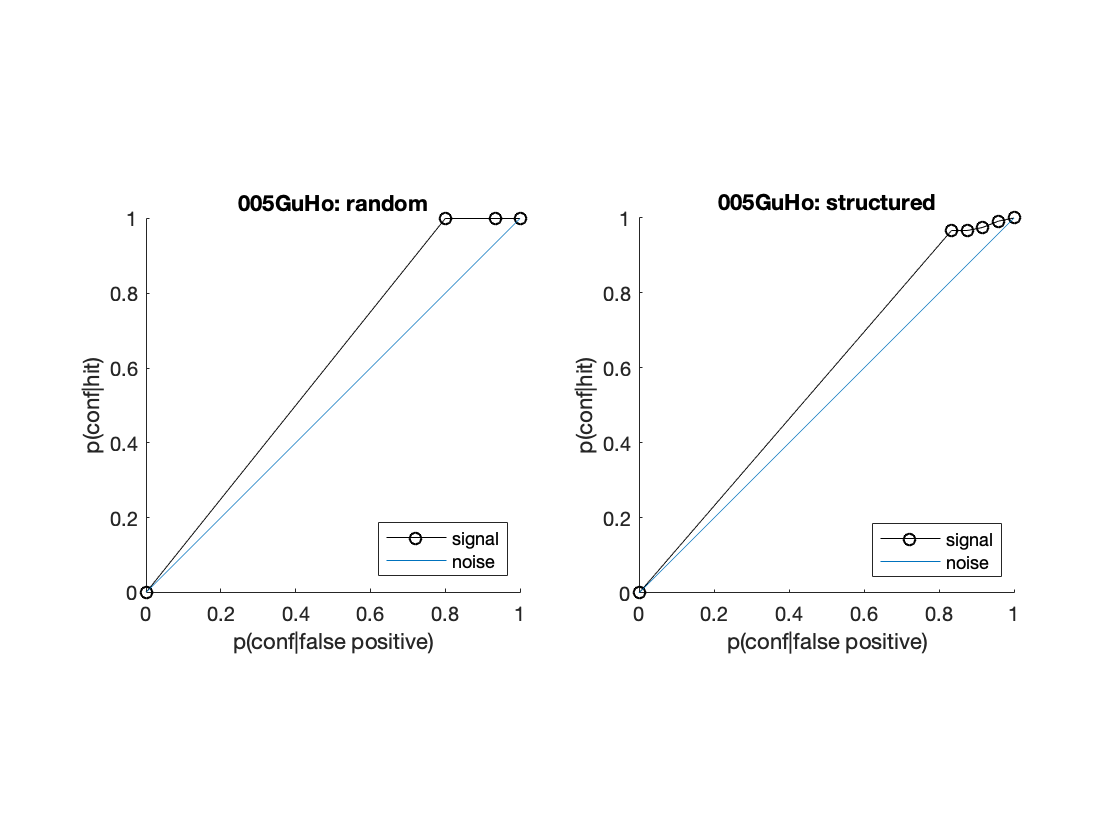

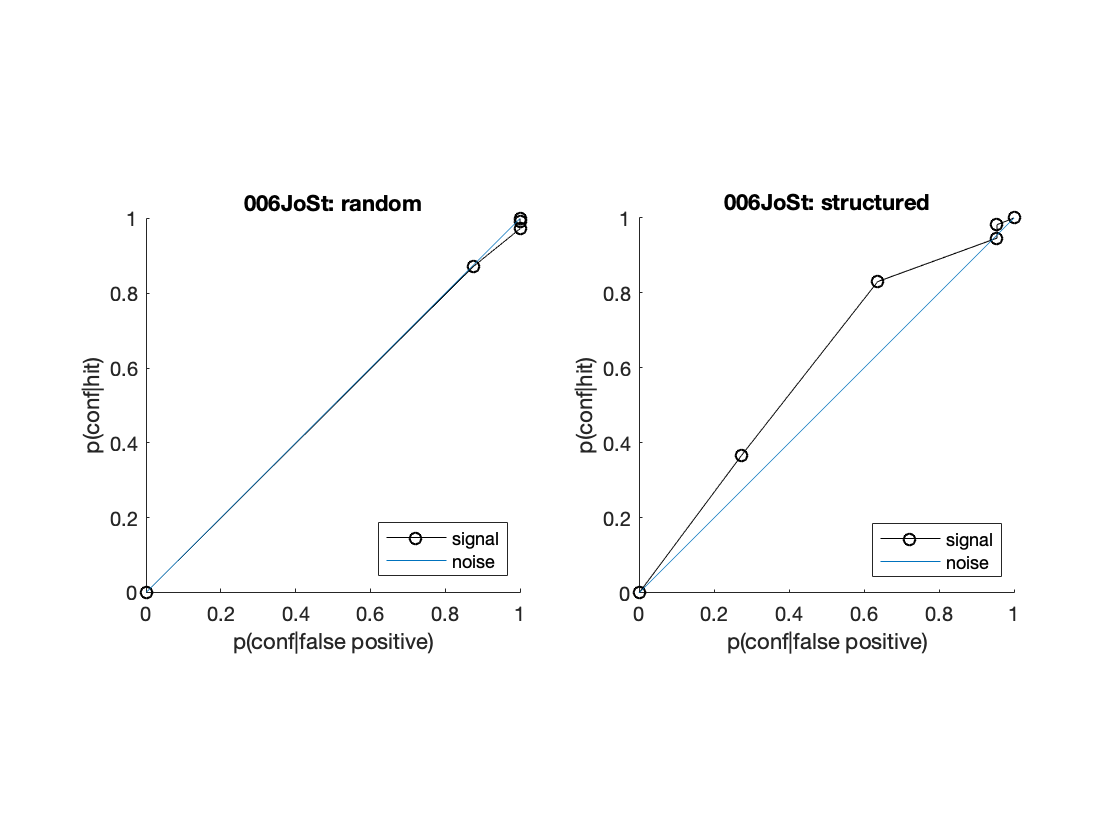

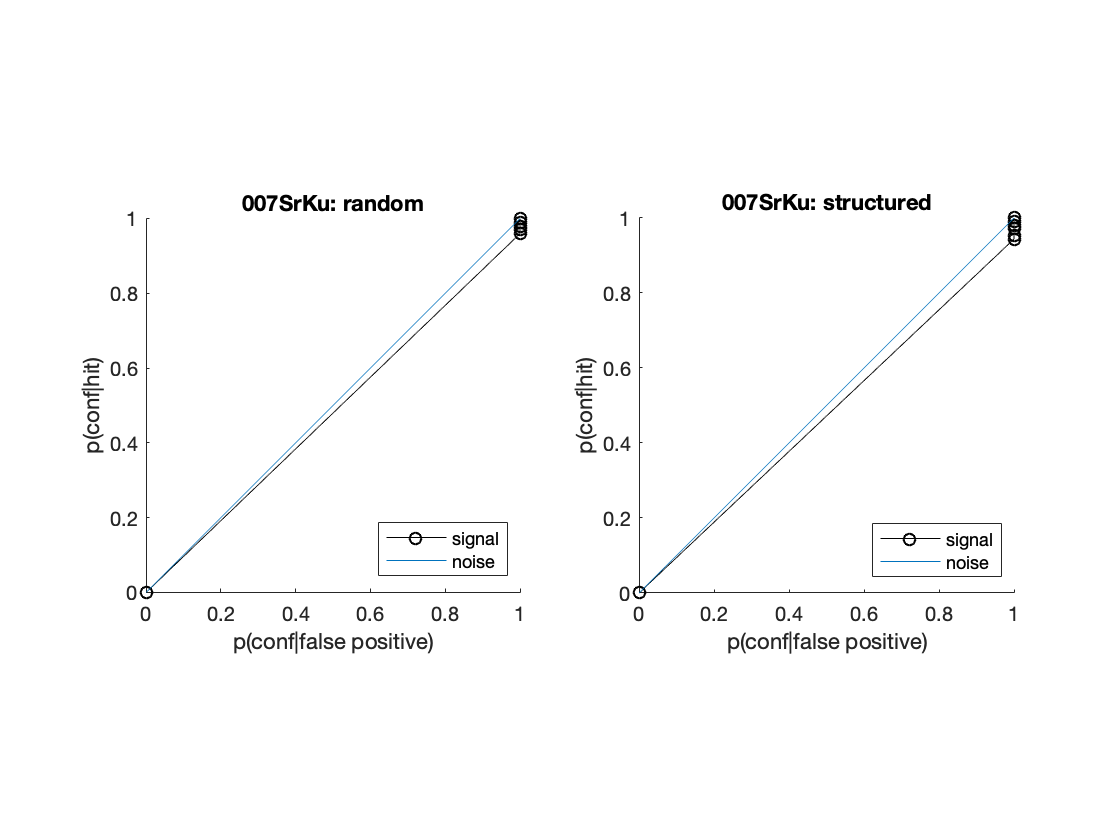

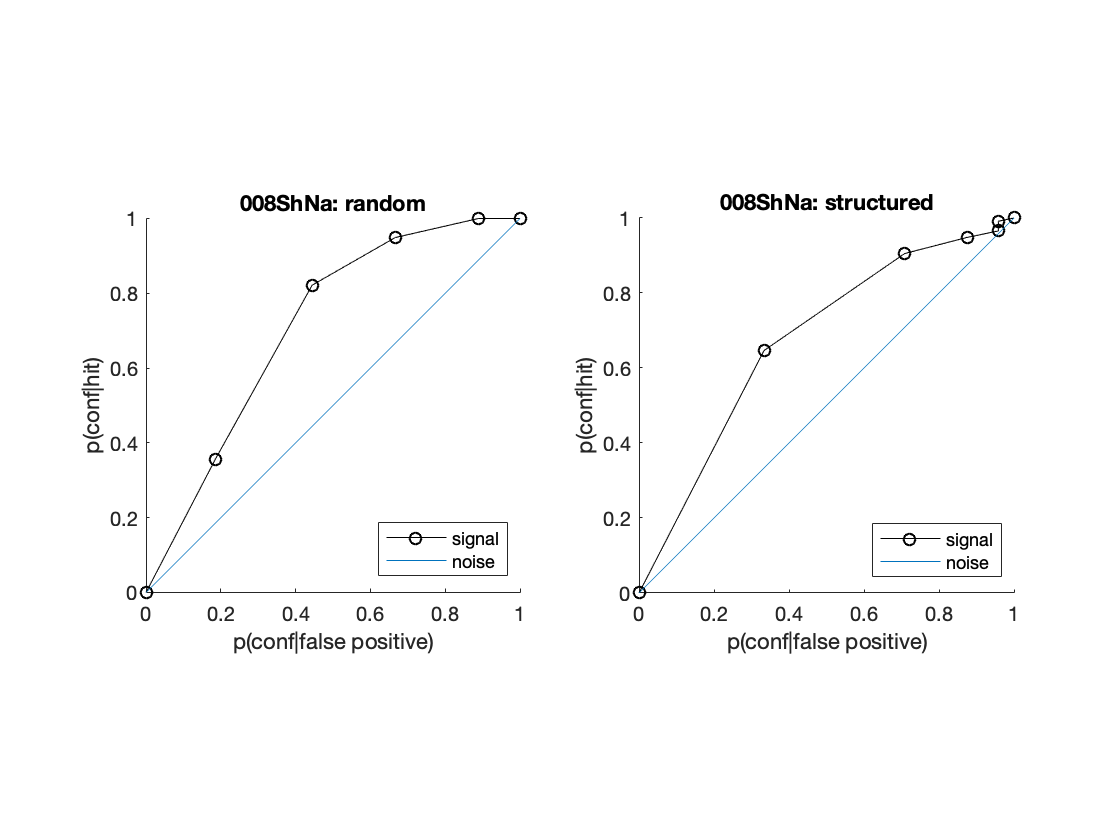

[StructSignalYesGroup, StructSignalNoGroup, StructNoiseYesGroup, StructNoiseNoGroup] = deal([]); %initialise with NaN values
[RandSignalYesGroup, RandSignalNoGroup, RandNoiseYesGroup, RandNoiseNoGroup] = deal([]); %initialise with NaN values
[nR_StructSignal,nR_StructNoise,nR_RandSignal,nR_RandNoise] = deal([]); %initialise with NaN values

for s=1:length(subj_list)
    subj = data_struct([subj_list{s}]);
    
    %break into taskXsignalXresponse
    StructSignalYes = histc(subj.StructConf(subj.StructSignal==1 & subj.StructResp==1),1:6);
    StructSignalNo = histc(subj.StructConf(subj.StructSignal==1 & subj.StructResp==0),1:6);
    StructNoiseYes = histc(subj.StructConf(subj.StructSignal==0 & subj.StructResp==1),1:6);
    StructNoiseNo = histc(subj.StructConf(subj.StructSignal==0 & subj.StructResp==0),1:6);
    
    RandSignalYes = histc(subj.RandomConf(subj.RandomSignal==1 & subj.RandomResp==1),1:6);
    RandSignalNo = histc(subj.RandomConf(subj.RandomSignal==1 & subj.RandomResp==0),1:6);
    RandNoiseYes = histc(subj.RandomConf(subj.RandomSignal==0 & subj.RandomResp==1),1:6);
    RandNoiseNo = histc(subj.RandomConf(subj.RandomSignal==0 & subj.RandomResp==0),1:6);
    
    nR_StructSignal(s,:) = [reshape(StructSignalNo(end:-1:1),1,[]) reshape(StructSignalYes,1,[])];
    nR_StructNoise(s,:) = [reshape(StructNoiseNo(end:-1:1),1,[]) reshape(StructNoiseYes,1,[])];
    nR_RandSignal(s,:) = [reshape(RandSignalNo(end:-1:1),1,[]) reshape(RandSignalYes,1,[])];
    nR_RandNoise(s,:) = [reshape(RandNoiseNo(end:-1:1),1,[]) reshape(RandNoiseYes,1,[])];
    

%     % plot random
%     
%     figure;
%     subplot(1,2,1);
%     hold on;
%     axis equal
%     
%     %random no responses
%     plot([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
%         [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)],'-ok');
%     
%     RandNoAUC(s) = trapz([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
%         [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)]);
%     
%     RandNoiseNoGroup(s,:) = [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)];
%     RandSignalNoGroup(s,:) = [0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)];
%     
%     xlabel('p(conf|false positive)');
%     ylabel('p(conf|hit)');
%     title([subj_list{s}, ': random']);
%     set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%     set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%     refline(1,0);
%     legend('signal', 'noise', 'Location', 'southeast')
%     
%     % plot structured
%     subplot(1,2,2);
%     hold on;
%     axis equal
%     
%     %structured no responses
%     plot([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
%         [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)],'-ok');
%     
%     StructNoAUC(s) = trapz([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
%         [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)]);
%     
%     StructNoiseNoGroup(s,:) = [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)];
%     StructSignalNoGroup(s,:) = [0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)];
%     
%     xlabel('p(conf|false positive)');
%     ylabel('p(conf|hit)');
%     title([subj_list{s}, ': structured']);
%     set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%     set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%     refline(1,0);
%     legend('signal', 'noise', 'Location', 'southeast')
%     set(0,'defaultAxesFontSize',10)

end

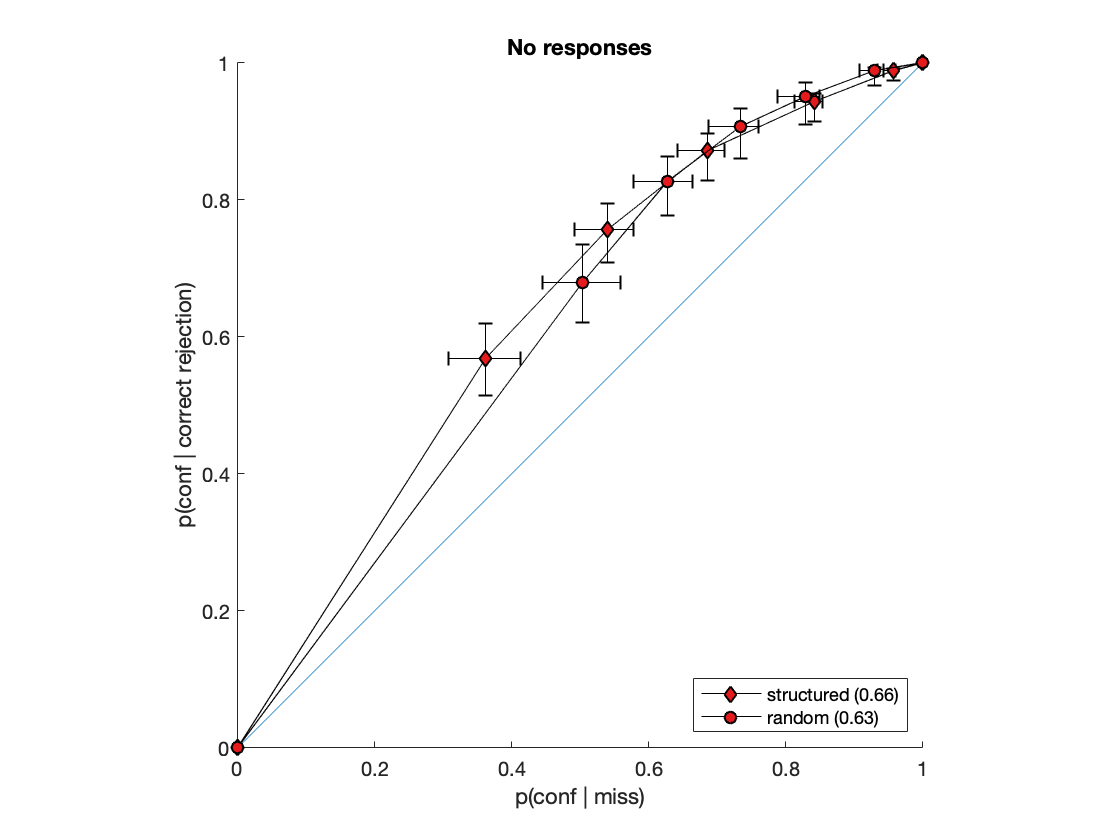

%Group plot
figure;
ax1=subplot(1,1,1);
hold on;
axis equal
refline(1,0);

%structured condition
errorbar(nanmean(StructSignalNoGroup),nanmean(StructNoiseNoGroup),nanstd(StructSignalNoGroup)/sqrt(length(subj_list)),nanstd(StructNoiseNoGroup)/sqrt(length(subj_list)),...
    nanstd(StructSignalNoGroup)/sqrt(length(subj_list)),nanstd(StructNoiseNoGroup)/sqrt(length(subj_list)),'k')
str_diamonds=plot(nanmean(StructSignalNoGroup),nanmean(StructNoiseNoGroup), '-dk', 'MarkerFaceColor',cb(1,:));

%random condition
errorbar(nanmean(RandSignalNoGroup),nanmean(RandNoiseNoGroup),nanstd(RandSignalNoGroup)/sqrt(length(subj_list)),nanstd(RandNoiseNoGroup)/sqrt(length(subj_list)),...
    nanstd(RandSignalNoGroup)/sqrt(length(subj_list)),nanstd(RandNoiseNoGroup)/sqrt(length(subj_list)),'k')
rand_circles=plot(nanmean(RandSignalNoGroup),nanmean(RandNoiseNoGroup), '-ok', 'MarkerFaceColor',cb(1,:));

%continue plotting
xlabel('p(conf | miss)');
ylabel('p(conf | correct rejection)');
title('No responses');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([str_diamonds,rand_circles],{sprintf('structured (%.02f)',nanmean(StructNoAUC)), sprintf('random (%.02f)',nanmean(RandNoAUC))}, 'Location', 'southeast')